# Compute the recovery probability of a 1-D dynamical system

System dynamics:


$$dX_t = cdt + dW_t$$


Define the function $h(x) = x$ and the safe set as 


$$$\mathcal{C} = \{x: h(x)\geq 0 \}$$$


If the initial point $x = x_0 \notin \mathcal{C}$. We would like to compute the recovery probability with time.

Suppose that $X_t = W_t+ ct$, where $W$ is a Brownian motion, $c$ is a constant. Set $H_a = \inf\{t: X_t=a\}$ for $a>0$. For $c\in\mathbb{R}$, the density of $H_a$ is


$$f_{H_a}(t)=\frac{a \exp\{\frac{-(a-ct)^2}{2t}\}}{\sqrt{2\pi t^3}}$$


% system parameters
a = 2; % safe set boundary
c = 0.4; % the coefficient in the dynamics \dot x = c x

% range of the time interval
t_max = 10;

% number of samples in t space
Nt = 10000;

% t grids
t1d = linspace(0,t_max,Nt);
dt = t1d(2) - t1d(1);

% probability density function 
f = a*exp(-(a-c*t1d).^2 ./ (2*t1d))./sqrt(2*pi*t1d.^3);
f(1) = 0;
F = cumsum(f)*dt;

## Data Generation

## (I) Use the PDE solver

### Step 1: Initialization 

sigma = 1;

% range of the state space 
x_min  = -20;  % x in [x_min, a]
t_max = 10;      % t in [0, t_max]

% number of samplines in (x,t) space 
Nx_part1 = 100;   
Nt = 10000;

% x and t grids 
% to guarantee that 0 is included in x1d, we separate x1d into two parts
% [x_min,0] and (0,a]
x1d_part1 = linspace(x_min,0,Nx_part1);   %[x_min, 0]
t1d = linspace(0,t_max,Nt);

% sampling interval (grid size)
dx = x1d_part1(2) - x1d_part1(1);
dt = t1d(2) - t1d(1);

x1d_part2 = dx:dx:a; % (0,a]
x1d = [x1d_part1, x1d_part2];
Nx = length(x1d);

% check if the grid size is appropriate 
if dt < 0.5*dx/c
    fprintf("approriate dt : dt << dx/c")
else
    fprintf("pick smaller dt")
end

approriate dt : dt << dx/c


[xx,tt] = ndgrid(x1d,t1d);
U = zeros(size(xx));    % main variable to be solved
                        % U(*t) = U(:,j) is U at time t = t1d(j) 
                

### Step 2: Build operators for dU/dt = d^2U/dx^2 term 

e = ones(Nx,1);
D = ((1/dx)^2) * spdiags([e -2*e e], -1:1, Nx, Nx);                 
A = speye(Nx) - dt*(sigma^2)*D;
AII = A(2:Nx-1,2:Nx-1);
AIR = A(2:Nx-1,Nx);
AIL = A(2:Nx-1,1);
% operation to be used later: 

### Step 3: Define terms for upwind scheme 

ind0 = 2:Nx-1; % interior points
indL = 1:Nx-2; % left shit, delete the last two indices
indR = 3:Nx;   % right shit, delete the first and second indices

### Step 4: Main solver

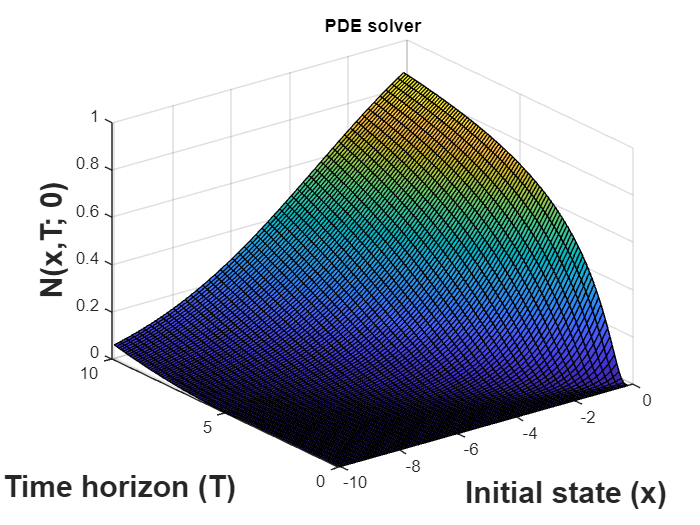

% initialization, U(x,0) = 1_M^c (x) boundary condition 
u = zeros(Nx,1);
u(Nx) = 1; 


% time evoluation 
for j = 2:Nt 
    
    % Advection 
    u_adv = u; 
    
    if c > 0
        u_adv(ind0) = u(ind0) + (dt*c/dx)*(u(indR)-u(ind0));
    else
        u_adv(ind0) = u(ind0) + (dt*c/dx)*(u(ind0)-u(indL));   
    end 
   
    % Diffusion
    u_dif = u_adv;
    u_dif(ind0) = AII\(u_adv(ind0)-AIR*u_adv(Nx));
    
    u = u_dif;
    
    U(:,j) = u; % U(x,t)
    
end

partial_U = (U(2:length(x1d),:) - U(1:length(x1d)-1,:))/dx;
surf(xx(50:99,1:100:10000),tt(50:99,1:100:10000),U(50:99,1:100:10000));
zlim([0,1]);
xlabel('Initial state (x)','FontSize',18,'FontWeight','bold');
ylabel('Time horizon (T)','FontSize',18,'FontWeight','bold')
zlabel('N(x,T; 0)','FontSize',18,'FontWeight','bold');
title('PDE solver');

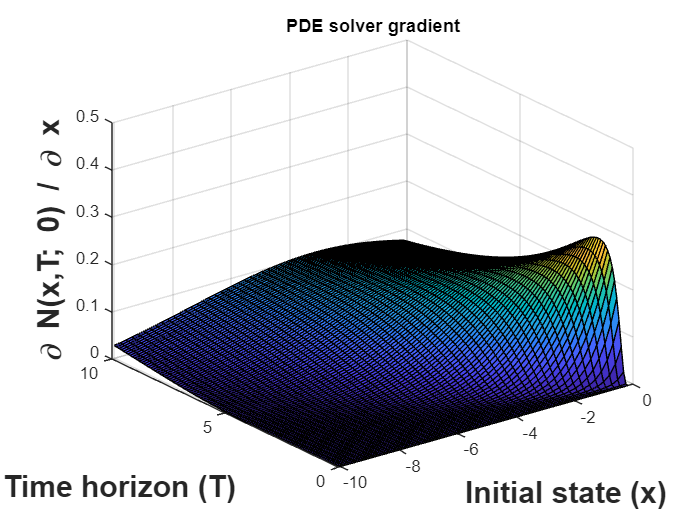


surf(xx(50:99,1:100:10000),tt(50:99,1:100:10000),partial_U(50:99,1:100:10000));
zlim([0,0.5]);
xlabel('Initial state (x)','FontSize',18,'FontWeight','bold');
ylabel('Time horizon (T)','FontSize',18,'FontWeight','bold')
zlabel('\partial N(x,T; 0) / \partial x','FontSize',18,'FontWeight','bold');
title('PDE solver gradient')

## **(II) Analytical solution**

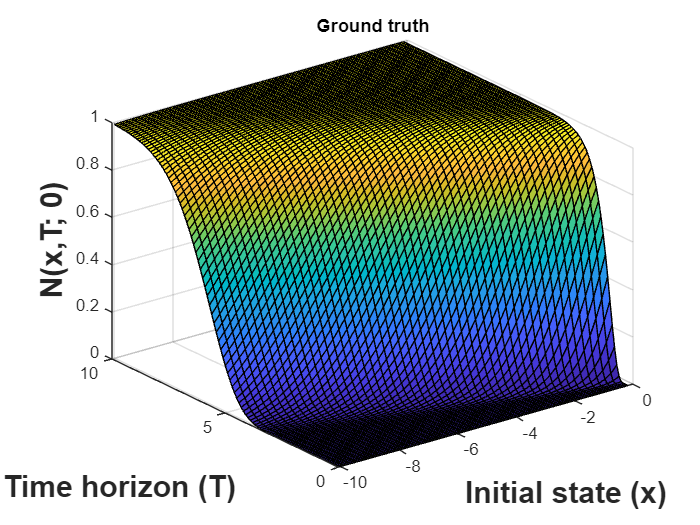

F2 = zeros(length(x1d),Nt);
for index = 1:length(x1d)
    f = (a-x1d(index))*exp(-((a-x1d(index))-c*t1d).^2 ./ (2*t1d))./sqrt(2*pi*t1d.^3);
    f(1) = 0;
    F2(index,:) = cumsum(f)*dt;
end

error_U = (1-U) ./ (1-F2);   
partial_F2 = (F2(2:length(x1d),:) - F2(1:length(x1d)-1,:))/dx;
surf(xx(50:99,1:100:10000),tt(50:99,1:100:10000),F2(50:99,1:100:10000));
zlim([0,1]);
xlabel('Initial state (x)','FontSize',18,'FontWeight','bold');
ylabel('Time horizon (T)','FontSize',18,'FontWeight','bold')
zlabel('N(x,T; 0)','FontSize',18,'FontWeight','bold');
title('Ground truth');

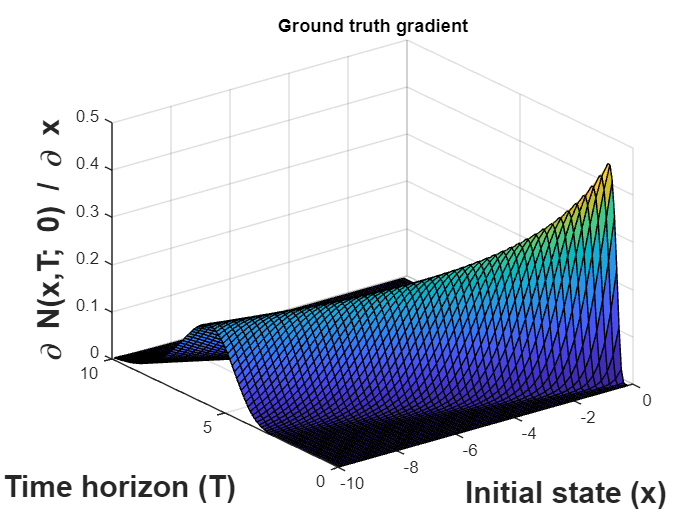


% save('ground_truth.mat', 'F2')

surf(xx(50:99,1:100:10000),tt(50:99,1:100:10000),partial_F2(50:99,1:100:10000));
zlim([0,0.5]);
% surf(xx(1:101,1:100:10000),tt(1:101,1:100:10000),error_U(1:101,1:100:10000));
xlabel('Initial state (x)','FontSize',18,'FontWeight','bold');
ylabel('Time horizon (T)','FontSize',18,'FontWeight','bold')
zlabel('\partial N(x,T; 0) / \partial x','FontSize',18,'FontWeight','bold');
title('Ground truth gradient')

## (III) Use the Monte Carlo (MC) Method

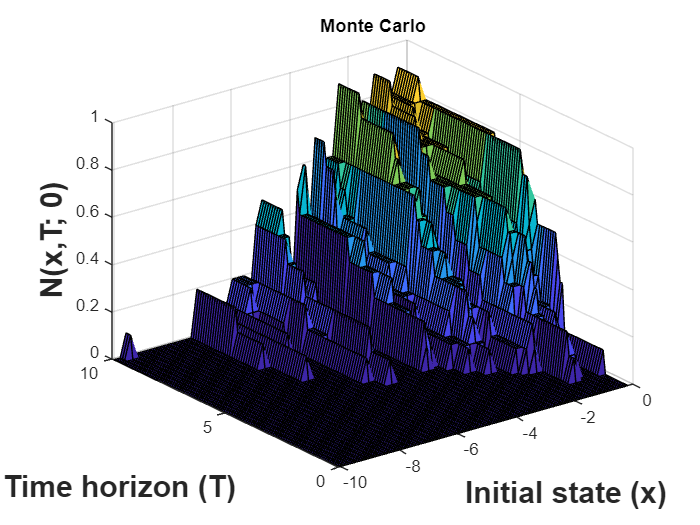

% store the position of x at different sample time.
loop_num = 10;
U2 = zeros(length(x1d),Nt);
for index = 1:length(x1d)
    % store the first exit time each loop
    first_recover_time = (Nt+1)*ones(loop_num,1);
    x = zeros(Nt,1);
    x(1)=x1d(index);
    for loop_count = 1:loop_num
        for i = 1:(Nt-1)
            x(i+1) = c*dt + randn*sqrt(dt) + x(i);
            if x(i+1) >= a
                first_recover_time(loop_count) = i+1;
                break
            end
        end
    end
    for loop_count = 1:loop_num
        if first_recover_time(loop_count)<(Nt+1)
            U2(index,first_recover_time(loop_count)) = U2(index,first_recover_time(loop_count))+1;
        end
    end
end
U2 = U2/loop_num;
U2 = cumsum(U2,2);
partial_U2 = (U2(2:length(x1d),:) - U2(1:length(x1d)-1,:))/dx;
error_U2 = (1-U2) ./ (1-F2);   
surf(xx(50:99,1:100:10000),tt(50:99,1:100:10000),U2(50:99,1:100:10000));
zlim([0,1]);
xlabel('Initial state (x)','FontSize',18,'FontWeight','bold');
ylabel('Time horizon (T)','FontSize',18,'FontWeight','bold')
zlabel('N(x,T; 0)','FontSize',18,'FontWeight','bold');
title('Monte Carlo');

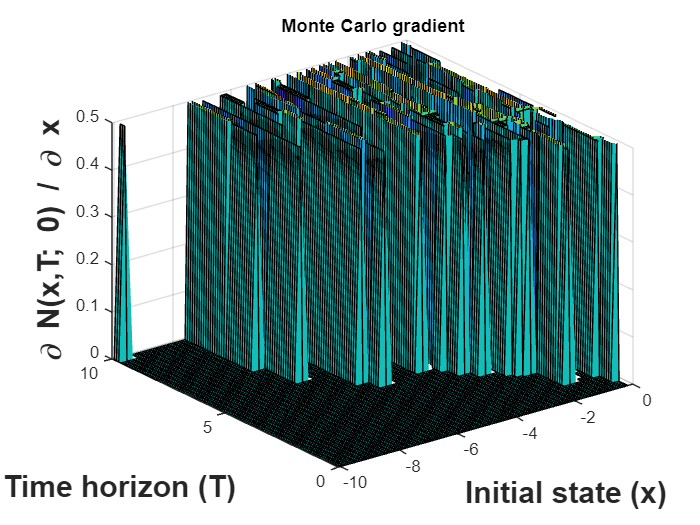


% save('MC1000_c12.mat', 'U2')

surf(xx(50:99,1:100:10000),tt(50:99,1:100:10000),partial_U2(50:99,1:100:10000));
zlim([0,0.5]);
xlabel('Initial state (x)','FontSize',18,'FontWeight','bold');
ylabel('Time horizon (T)','FontSize',18,'FontWeight','bold')
zlabel('\partial N(x,T; 0) / \partial x','FontSize',18,'FontWeight','bold');
title('Monte Carlo gradient');